# Tablice

Matlab stworzono, by pracować na tablicach/macierzach. Łatwo je tworzyć i wiele funkcji czy działań operuje na całych tabliach. Wektory i macierze wykorzystywane są do przechowywanie danych tego samego typu.

-    rozmiar macierzy to $w\times k$, gdzie $w$ to liczba wierszy, a $k$ to liczba kolumn,

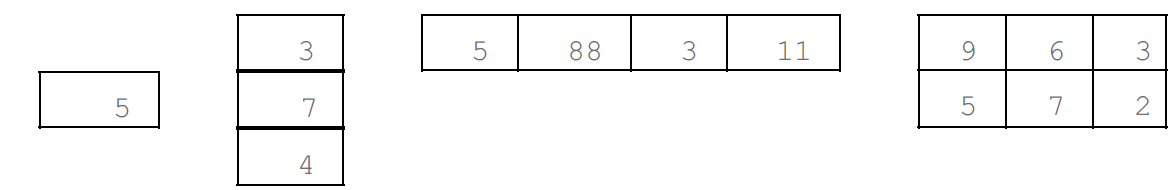

- **wektor** to tablica 1-wymiarowa: wektor kolumnowy ma jedną kolumnę i $n$ rzędów (rozmiar $n\times 1$); wektor wierszowy ma 1 wiersz i $n$ kolumn (rozmiar $1\times n$),

- **skalar** to liczba, czyli tablica o rozmiarze $1\times 1$.  

## Wektory

### Tworzenie wektorów rzędowych(wierszowych)

#### 1. Umieszczając w nawiasie kwadratowym wartości wektora 

v = [1 2 3 4]

v =      1     2     3     4


**Ćwiczenie:** Utwórz 3 zmienne zawierające 3 różne wektory wierszowe: 

A = [2 4 6 8]

A =      2     4     6     8


B = [2 1 3 7]

B =      2     1     3     7


C = [1 1 1 1 1 1 1 1 1 1]

C =      1     1     1     1     1     1     1     1     1     1


#### 2. Korzystając z notacji dwukropkowej

wek = 1:5    % w tym przypadku nawiasy nie są konieczne

Można podać krok, z jakim dodawane są liczby do wektora. Np. by utworzyć wektor ze wszystkimi co drugimi liczbami z zakresu 1 do 9 należy napisać:  

nv = 1:2:9

**Pytanie 1**: co się stanie, jeśli po dodaniu kroku otrzymana liczba będzie większa od górnego zakres? Proszę się zastanowić, a potem sprawdzić.

1:2:9

ans =      1     3     5     7     9


**Pytanie 2**: Jak można stworzyć poniższy wektor przy pomocy notacji dwukropkowej?

  `9     7     5     3     1 `

9:-2:1

ans =      9     7     5     3     1


#### 3. Korzystając z funkcji` linspace()`

Funkcja `linspace(x,y,n)` tworzy wektor o $n$ równomiernie rozłożonych wartościach z zakresu $x$ do $y$.

lista = linspace(3, 15, 5)

Łącząc dwa istniejące wektory.

newvec = [nv lista]

### Odwoływanie się do elementów wektora

Elementy wektora są numerowane (przypisywane im są ***indeksy***) po kolei zaczynając od 1. Poniżej pokazane są indeksy poszczególnych elementów wektora `newvec`.

 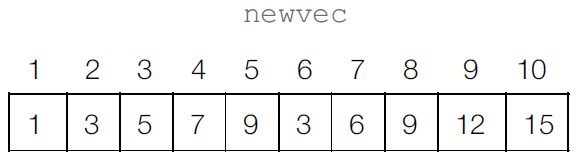

Aby wywołać dany element tablicy, podajemy jego indeks w nawiasie okrągłym po nazwie tablicy:

newvec(5)

Można utworzyć nowy wektor będący częścią starego odpowiednio zadając zakres indeksów:

b = newvec(4:6)

Można użyć dowolnego wektora indeksów:

newvec([1 5 10])

### Przypisywanie nowych wartości elementom wektora

Wywołujemy dany element wektora i przypisujemy mu nową wartość

b(2) = 11

**Uwaga**: Można odwołać się do indeksu, którego jeszcze nie ma. Spowoduje to odpowiednie powiększenie tablicy.

rv = [3 55 11]
rv(4) = 2

Jeśli pojawi się przerwa między elementami, zostanę one wypełnione zerami.

rv(6) = 13

### Tworzenie wektorów kolumnowych

Wektory kolumnowe tworzy się oddzielając elementy średnikiem

c = [1; 2; 3; 4]

Aby móc korzystać z notacji dwukropkowej, trzeba wykorzystać operator `'`: 

r = 1:3;      % średnik zapobiega wyświetleniu wartości na ekranie
c = r'

## Tablice

Tworzenie tablic to uogólnienie tworzenia wektorów: elementy w rzędach są oddzielane spacjami lub przecinkami, a rzędy oddzielone są średnikiem:

mat = [4 3 1; 2 5 6]

**Uwaga: **musi być taka sama liczba elementów w każdym rzędzie. Proszę zmodyfikować poniższe polecenie tak, aby nie pojawiał się komunikat błędu.

mat = [3 5 7; 1 2 0]

Można także korzystać z notacji dwukropkowej:

mat = [2:4; 3:5]

### Funkcje do tworzenia specjalnych tablic 

Tablice wypełnione losowymi liczbami z zakresu $\left(0,1\right)$ tworzy funkcja `rand()`. Podanie pojedynczego argumentu $n$tworzy kwadratową tablicę o rozmiarze $n\times n$ 

rand(2)

Podanie dwóch argumentów spowoduje utworzenie tablicy $m\times n$

rand(1,3)

Aby utworzyć np. tablicę wypełnioną losowymi liczbami całkowitymi z zakresu $\left(0,10\right)\;$można skorzystać z instrukcji `round()`: 

round(rand(2,2)*10)

**Ćwiczenie:** proszę utworzyć tablicę 4 wierszach i 2 kolumnach zawierającą całkowite liczby losowe z przedziału $\left(0,100\right)$

round(rand(4,2)*100)

Tablicę wypełnioną zerami tworzy instrukcja `zeros()`:

zeros(3)

Tablicę wypełnioną jedynkami tworzy instrukcja `ones()`:

ones(2,4)

ans =     42    66
    92     4
    79    85
    96    93


### Odwoływanie się do i modyfikowanie elemenetów tablicy.

Aby odwołać się do danego elementu tablicy, trzeba podać 2 liczby: numer wiersza i numer kolumny, gdzie się znajduje.

mat = [2:4; 3:5]
mat(2,3)

Można także odwołać się do kawałka tablicy podając odpowiedni zakres indeksów rzędów i kolumn. Przecinek oddziela zakresy indeksów rzędów od zakresu indeksów kolumn.

mat(1:2,2:3)

Do wybrania całego rzędu lub kolumny służy `:`.

mat(1,:)

mat(:,2)

Można użyć pojedynczego indeksu, wtedy tablica będzie rozwijana kolumna po kolumnie:

intmat = [100 77; 28 14]

intmat(1)

intmat(2)

intmat(3)

intmat(4)

W podobny sposób można przypisać nową wartość danemu elementowi.

mat = [2:4; 3:5]
mat(1,2) = 11

Można zmieniać wartości całych rzędów/kolumn. 

mat(2,:) = 5:7

**Uwaga:** rozmiar wektora zastępującego rząd/kolumnę musi być taki sam, jak rozmiar rzędu/kolumny.

Można rozszerzyć tablicę dodając cały rząd lub kolumnę.

mat(:,4) = [9 2]'

Podobnie jak w przypadku wektorów, gdy rozszerzamy tablicę, puste miejsca zostaną wypełnione zerami.

mat(4,:) = 2:2:8

Matlab ma wbudowane wyrażenie end, które można wykorzystać do odwołania się do ostatniego elementu wektora.

mat = [1:3; 4:6]'
mat(end,2)
mat(1,end)
mat(end-1,2)